clear
clf
load('data/gauntlet_data.mat')
load('data/gauntlet_scans.mat')
r = r_all(:,1);
theta = theta_all(:,1);
f = 0

f = 0

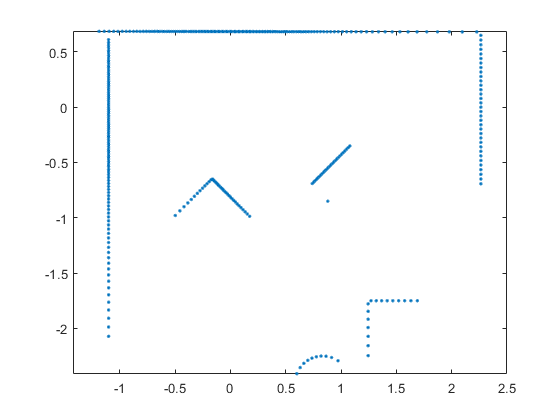

r_clean_index = find((r ~= 0) & (r < 3));
r_clean = r(r_clean_index);
theta_clean = theta(r_clean_index);
[x, y] = pol2cart(theta_clean, r_clean);
points = [x y];
resolution = 0.05;
offset = 0.5;
x_grid = resolution * round((min(x)-offset:resolution:max(x)+offset) / resolution);
y_grid = resolution * round((min(y)-offset:resolution:max(y)+offset) / resolution);
[x, y] = meshgrid(x_grid, y_grid);
f = 0;
clf
plot(points(:,1), points(:,2), '.')
axis equal

% find walls
d = 0.01

d = 0.0100

n = 500

n = 500

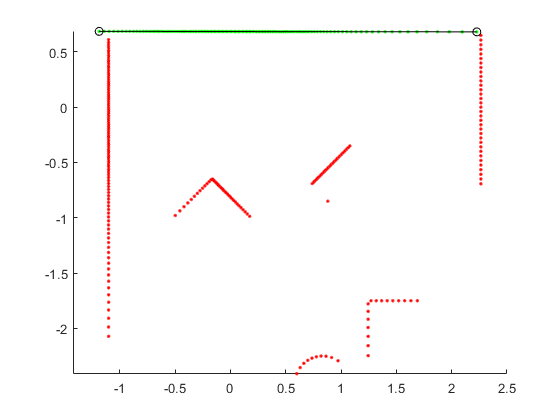

wall_weight = 0.0125;

[endpoints_wall1, inliers_wall1, outliers_wall1, m, b] = ransac_line_fit(points, d, n, 0, 1);

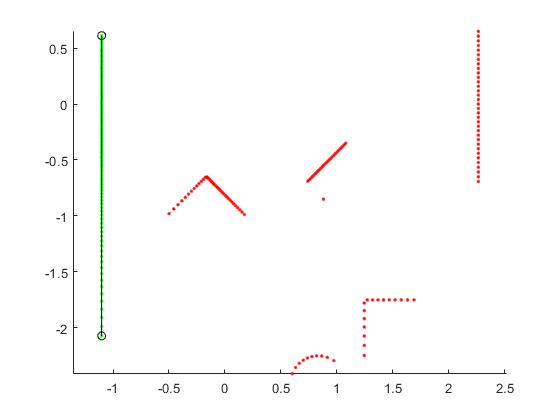

[endpoints_wall2, inliers_wall2, outliers_wall2, m, b] = ransac_line_fit(outliers_wall1, d, n, 0, 1);

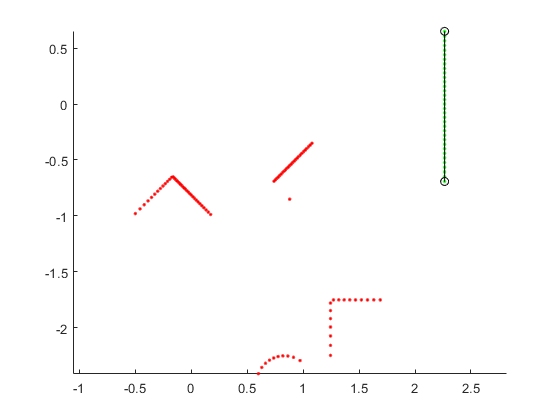

[endpoints_wall3, inliers_wall3, outliers_wall3, m, b] = ransac_line_fit(outliers_wall2, d, n, 0, 1);


inliers = [inliers_wall1; inliers_wall2; inliers_wall3];
for j=1:length(inliers)
    f = f - wall_weight * (log(sqrt((x-inliers(j,1)).^2 + (y-inliers(j,2)).^2)));
end

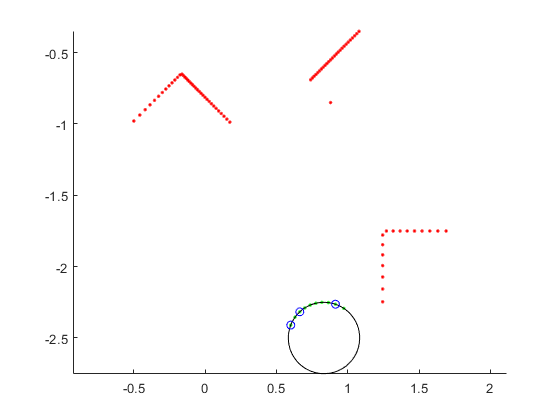

d = 0.01;
n = 5000;
r_max = 0.3;
circle_weight = 1;

[endpoints_circle, inliers_circle, outliers_circle, near_matches_circle, center, radius] = ransac_circle_fit(outliers_wall3, r_max, d, n, 1);



% place sink at circle center
f = f + circle_weight * log(sqrt((x-center(1)).^2 + (y-center(2)).^2));

remainders = outliers_circle;

d = 0.01

d = 0.0100

n = 1000

n = 1000

obstacle_weight = 0.0125;

endpointsx = [];
endpointsy = [];

while length(remainders) >= 3
    [endpoints, inliers, remainders, m, b] = ransac_line_fit(remainders, d, n, 1, 0);
    for j=1:length(inliers)
        f = f - obstacle_weight * (log(sqrt((x-inliers(j,1)).^2 + (y-inliers(j,2)).^2)));
    end
    endpointsx = [endpointsx; endpoints(:,1)'];
    endpointsy = [endpointsy; endpoints(:,2)'];
end

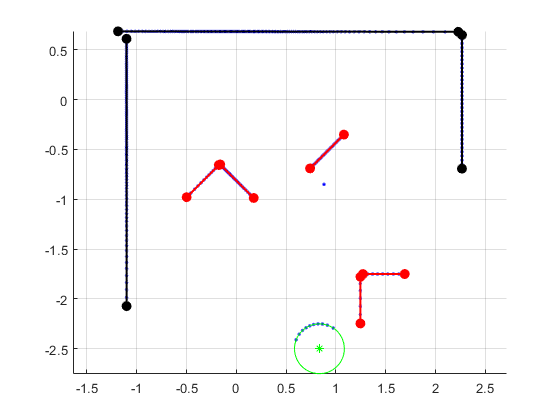

clf
hold on

% plot points
plot(points(:,1), points(:,2), 'b.')

% plot circle
plot_circle(center, radius, 'g-')
plot(center(1), center(2), 'g*')

% plot walls
plot(endpoints_wall1(:,1), endpoints_wall1(:,2), 'ko-', 'MarkerFaceColor', 'k', 'LineWidth', 1.5);
plot(endpoints_wall2(:,1), endpoints_wall2(:,2), 'ko-', 'MarkerFaceColor', 'k', 'LineWidth', 1.5);
plot(endpoints_wall3(:,1), endpoints_wall3(:,2), 'ko-', 'MarkerFaceColor', 'k', 'LineWidth', 1.5);

for i=1:length(endpointsx)
    plot(endpointsx(i,:), endpointsy(i,:), 'ro-', 'MarkerFaceColor', 'r', 'LineWidth', 1.5);
end

grid on
axis equal

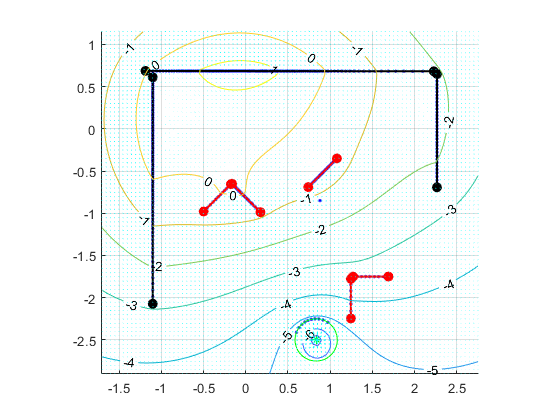

contour(x, y, f, 'ShowText', 'On')
[u, v] = gradient(f);
quiver(x, y, -u, -v, 'c')

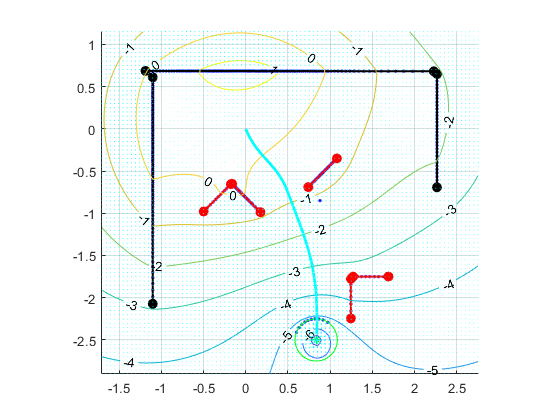

% Find path of robot from origin
r = [0 0];
lambda = .75;
delta = 0.99;
threshold = -5;
r_pos = [];
while 1
    r_pos = [r_pos; r];
    r_round = resolution * round(r / resolution);
    r_grad = -[u(y_grid == r_round(2), x_grid == r_round(1)), v(y_grid == r_round(2), x_grid == r_round(1))] * lambda;
    quiver(r(1), r(2), r_grad(1), r_grad(2), 'c', 'LineWidth', 2, 'MaxHeadSize', 0.5)
    
    r = r + r_grad;
    %z = double(subs(f, [x, y], [r(1), r(2)]));
    lambda = lambda * delta;
    
    %if f(y_grid == r_round(2), x_grid == r_round(1)) < threshold
    distance_from_center = r - center;
    if norm(distance_from_center) < .1
        r_pos = [r_pos; r];
        break
    end
end

% Dataset row format
% [timestamp, positionLeft, positionRight, AccelX, AccelY, AccelZ];
dtime = diff(dataset(:, 1));
mV_L = diff(dataset(:, 2)) ./ dtime;
mV_R = diff(dataset(:, 3)) ./ dtime;
time = dataset(2:end, 1) - dataset(2, 1);

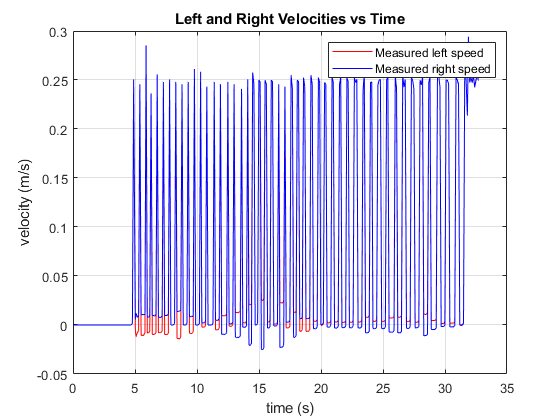

clf
plot(time, mV_L, 'r-', time, mV_R, 'b-')
title('Left and Right Velocities vs Time')
xlabel('time (s)')
ylabel('velocity (m/s)')
legend('Measured left speed', 'Measured right speed')
grid on

d_num = 0.235;
mV_T = (mV_L + mV_R) / 2;
mw = (mV_R - mV_L) / d_num;

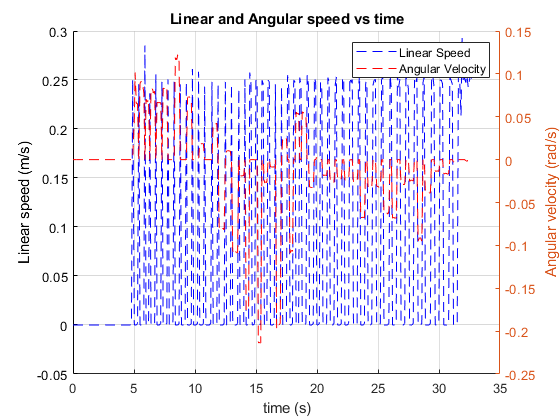

clf
hold on
plot(time, mV_T, 'b--');
xlabel('time (s)')
ylabel('Linear speed (m/s)')

yyaxis right
plot(time, mw, 'r--')
xlabel('time (s)')
ylabel('Angular velocity (rad/s)')

title('Linear and Angular speed vs time')
legend('Linear Speed', 'Angular Velocity')
grid on
hold off

m_angle = zeros(size(mw));
angle = atan2(((r_pos(2,2)-r_pos(1,2))) , ((r_pos(2,1)-r_pos(1,1))));

m_vel = zeros(size(mV_T, 1), 2);
m_pos = zeros(size(mV_T, 1), 2);
pos = [r_pos(1, 1), r_pos(1, 2)];

% Solve the integrals to generate position
for n=1:length(dtime)
    angle = angle + mw(n) * dtime(n);
    m_angle(n) = angle;
    
    rot = [
        cos(angle) -sin(angle);
        sin(angle) cos(angle)
    ];
    
    mV = (rot * [mV_T(n); 0])';
    m_vel(n, :) = mV;
    pos = pos + (mV .* dtime(n));
    m_pos(n, :) = pos';
end

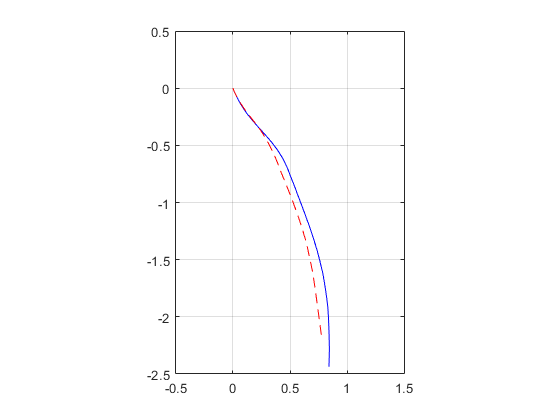

clf
plot(r_pos(:, 1), r_pos(:, 2), 'b', m_pos(:, 1), m_pos(:, 2), 'r--')
axis equal
xlim([-0.5 1.5])
ylim([-2.5 0.5])
grid on

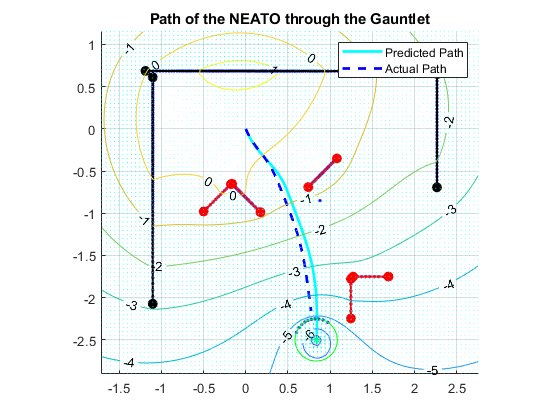

clf
hold on

% paths first for the legend
plot(r_pos(:, 1), r_pos(:, 2), 'c', m_pos(:, 1), m_pos(:, 2), 'b--', 'LineWidth', 2)

% plot points
plot(points(:,1), points(:,2), 'b.')

% plot circle
plot_circle(center, radius, 'g-')
plot(center(1), center(2), 'g*')

% plot walls
plot(endpoints_wall1(:,1), endpoints_wall1(:,2), 'ko-', 'MarkerFaceColor', 'k', 'LineWidth', 1.5);
plot(endpoints_wall2(:,1), endpoints_wall2(:,2), 'ko-', 'MarkerFaceColor', 'k', 'LineWidth', 1.5);
plot(endpoints_wall3(:,1), endpoints_wall3(:,2), 'ko-', 'MarkerFaceColor', 'k', 'LineWidth', 1.5);

for i=1:length(endpointsx)
    plot(endpointsx(i,:), endpointsy(i,:), 'ro-', 'MarkerFaceColor', 'r', 'LineWidth', 1.5);
end

grid on
axis equal

contour(x, y, f, 'ShowText', 'On')
[u, v] = gradient(f);
quiver(x, y, -u, -v, 'c')

legend('Predicted Path', 'Actual Path')
title('Path of the NEATO through the Gauntlet')

m_DL = diff(dataset(:, 2));
m_DR = diff(dataset(:, 3));
m_d = (m_DL + m_DR) / 2;
total_distance = sum(m_d)

total_distance = 2.3239